clear;

N = 150;
taum = 7;
g = 1.5;
omega0 = 1.0;
z = -0.1 + 1j*0.6;


% Theoretical sync. frequency
mu = 1 / taum;
p = [1 -omega0 mu^2+g*mu -omega0*mu^2];
eqOmegas = roots(p).';

% Keep the real root (if any)
for k=1:numel(eqOmegas)
    if isreal(eqOmegas(k))
        Omega = real(eqOmegas(k));
    end
end

AVG = mu^2 / (Omega^2 + mu^2);

D = eye(N);

n_trials = 1000;
arrDet = zeros(n_trials,1);
arrDet2 = zeros(n_trials,1);
errDet = zeros(n_trials,1);

for i=1:n_trials
    tau0 = exprnd(taum, N);
    avg = mean(cos(Omega*tau0), 'all');
    X = cos(Omega*tau0).*exp(-z*tau0);
    Y1 = eye(N) - g*X./(z + g*repmat(sum(cos(Omega*tau0),2),1,N)/N);
    newDet = det(Y1);
    Y2 = eye(N) - g*X/(z + g*avg)/N;
    y = z + g*avg;
    newDet2 = det(Y2);
    arrDet(i) = newDet;
    arrDet2(i) = newDet2;
    errDet(i) = mean(repmat(sum(cos(Omega*tau0),2),1,N)/N - AVG, 'all');
end

AVG2 = 1 - g*mu*(mu + z) / ((mu+z)^2 + Omega^2)/(z + g*AVG);
disp(AVG2);

  -0.2299 + 0.6398i



disp(mean(abs(arrDet)));

  4.7287e+292



disp(var(arrDet));

   Inf



disp(mean(abs(arrDet2)));

   7.6239e+04



disp(var(arrDet2));

   3.0489e+12



disp(mean(errDet));

  -5.0531e-05




disp(max(arrDet));

 -4.2248e+295 +1.0372e+295i



disp(min(arrDet));

  2.0949e+272 -1.1352e+273i



disp(max(arrDet2));

  -1.8389e+06 + 5.1208e+07i



disp(min(arrDet2));

  -0.0350 + 0.0644i



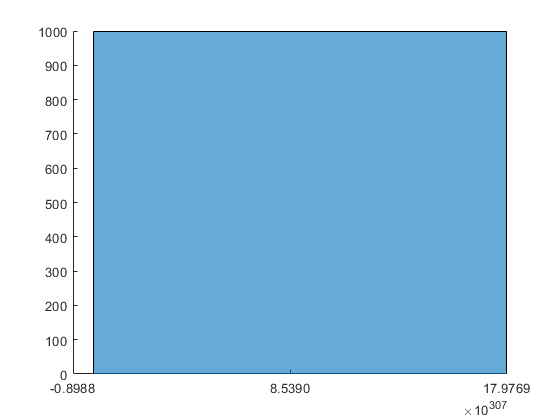

figure;
hold on;
histogram(abs(arrDet))

% histogram(arrDet2)